# Late self-similar solution for the drainage of an unconfined aquifer

set_demo_defaults, clear

This example follows the paper Zheng et al. (2013). We consider the drainage of an unconfined linear aquifer with vertical variation in both porosity and hydraulic conductivity.  Any vertical property variation can be accomodated, but here we assume the form a power-laws

$\phi(z) = \phi_0 z^m$ and $K(z) = K_0z^n$ where typically $n/m \in\left[2,\,3\right]$. 

m_vec = linspace(0,3,7)

m_vec = 0

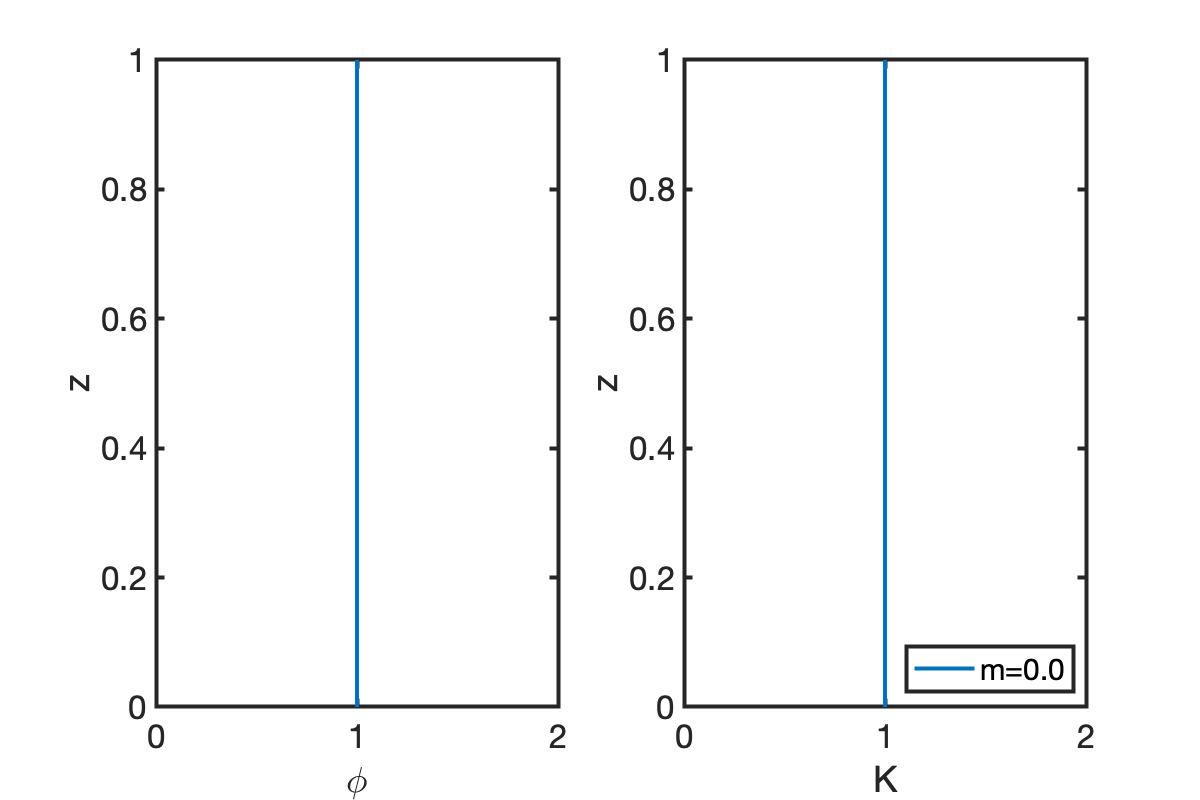

n_vec = 3*m_vec;
z = linspace(0,1,1e2);

figure('position',[10 10 600 400])
for i=1:length(m_vec)
subplot 121
plot(z.^m_vec(i),z), hold on
xlabel '\phi'
ylabel 'z'

subplot 122
plot(z.^n_vec(i),z), hold on
xlabel 'K'
ylabel 'z'
end
legend('m=0.0','m=0.5','m=1.0','m=1.5','m=2.0','m=2.5','m=3.0','location','southeast')

This allows for self-similar solutions that give insight and can be used to check the numerical simulations. The vertically integrated fluid mass balance id given by

$\frac{\partial }{\partial t}\int_0^{h} \phi(z)\, \mathrm{d}z - \int_0^{h} K(z) \nabla h\,  \mathrm{d}z = 0$ on $x\in\left[0,\,l\right]$

Integrating we can write the accumulation term several ways

 
$$\frac{\partial}{\partial t}\int_0^h\phi(z)\,\mathrm{d}z = \frac{\phi_0}{m+1}\frac{\partial h^{m+1}}{\partial t} = \phi_0 h^m \frac{\partial h}{\partial t} = \phi(h)  \frac{\partial h}{\partial t} $$


where the last expression shows that the porosity takes the role of the storativity in an unconfined aquifer. Integrating the flux term we obtain


$$- \int_0^{h} K(z) \nabla h\,  \mathrm{d}z = -\frac{K_0}{n+1}h^{n+1}\nabla h$$


The governing equation can then be written as

$\frac{\partial h^{m+1}}{\partial t}-D_h\nabla\cdot\left[h^{n+1}\nabla h\right] = 0$ on $x\in\left[0,\,l\right]$

where $D_h = \frac{K_0(m+1)}{\phi_0(n+1)}$ is the effective hydraulic diffusivity of the aquifer.

## Late self-similar solution

This problem has a both an early and a late self-similar solution. The early solution was governs the initial resonse before the change in the head interacts with the other boundary. The late self-similar solution becomes relevant once the head is dropping across the entire aquifer

% make grid so that last cell center is exactly 1;
Nx = 1000;
dx = 1/(Nx-.5);
xmax = Nx*dx;

Grid.xmin = 0; Grid.xmax = xmax; Grid.Nx = Nx;
Grid.geom = 'cartesian'

Grid = struct with fields:
    xmin: 0
    xmax: 1.0005
      Nx: 1000
    geom: 'cartesian'


Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
fs = zeros(Grid.Nx,1);   % r.h.s
M = Grid.dx/2*abs(G);   % mean operator

%% Residual
F1  = @(u,n) spdiags(M*u.^(n+1),0,Nx+1,Nx+1);
f2  = @(u,n,m) (m+1)/(n-m+1)*u.^(m+1);
res = @(u,n,m) D*(F1(u,n)*G*u)+f2(u,n,m);

%% Boundary conditions - for update!
BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = 0;
BC.dof_neu = [];
BC.dof_f_neu = [];
BC.qb = [];
[B,N,I] = build_bnd(BC,Grid,I);

### Solve directly

Due to the arbitrary nature of the exponents the non-linearity of this ODE can be incresed until the Newton fails - at least for simple initial guesses. For the case of constant coefficients (m=0, n=0) the ODE is still non-linear, but converges after some initial iterations. If we increase m (n=3*m) the Newton takes more iterations and eventually fails to converge around m ~ 0.3.

% Note: This will break at m ~ 0.3
m = .0; n = 3*m; kmax= 30;
% initial guess
u = 1-Grid.xc;
u = solve_self_similar_ode(res,u,n,m,B,N,BC,kmax);

it = 1: nres = 4.99e+05  ndu = 1.82e+01
it = 2: nres = 1.25e+05  ndu = 8.08e+00
it = 3: nres = 3.12e+04  ndu = 2.88e+00
it = 4: nres = 7.79e+03  ndu = 7.84e-01
it = 5: nres = 1.92e+03  ndu = 1.94e-01
it = 6: nres = 4.18e+02  ndu = 4.50e-02
it = 7: nres = 4.34e+01  ndu = 8.25e-03
it = 8: nres = 4.34e-01  ndu = 6.45e-04
it = 9: nres = 3.81e-05  ndu = 5.38e-06
it = 10: nres = 3.15e-09  ndu = 4.60e-10


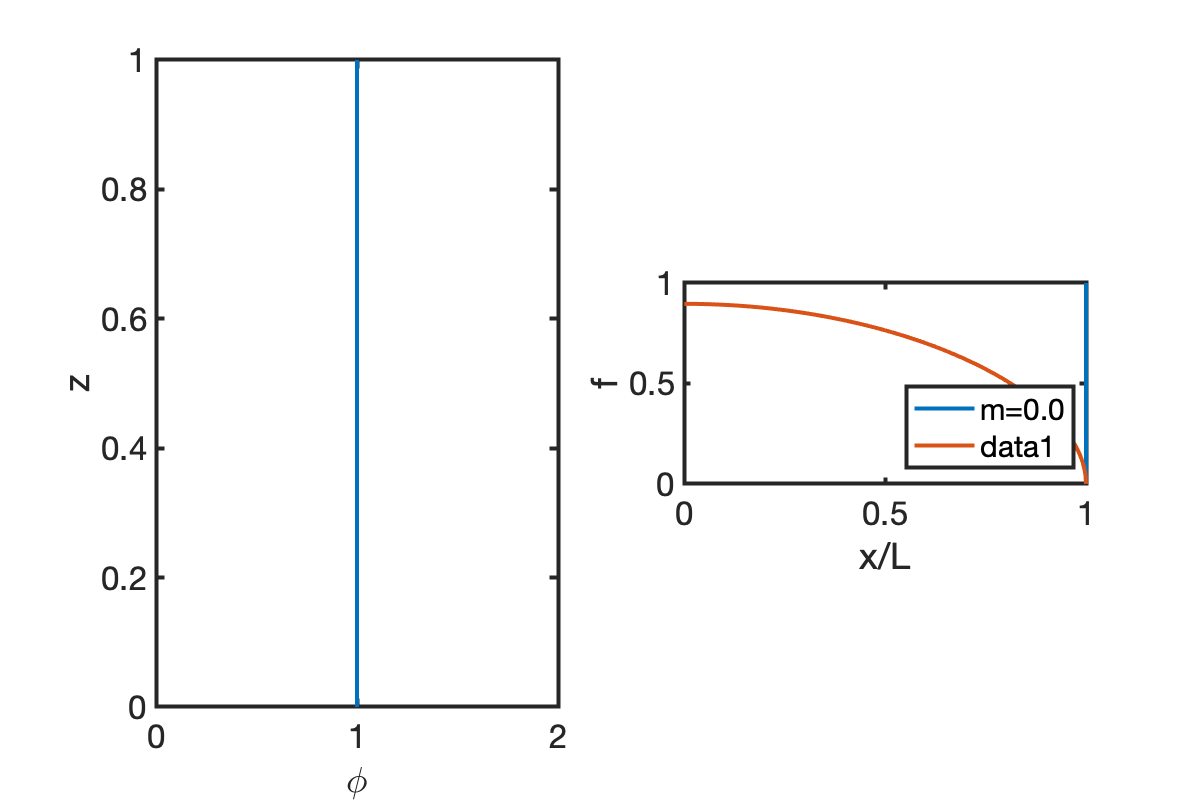

plot_self_similar_soln(Grid,u,n,m)

### Load stepping

A common strategy to deal with the failure of Newton-Raphson to converge for the more non-linear problems if called **load stepping**.The term comes  from mechanics where Newton-Raphson may fail to converge for large loads that cause large deformations. The idea is simply to gradually apply larger loads and always use the previous solution as an initial guess. 

In our case, we can start with the simpler case $m=n=0$ and then gradually increase $m$ ($n=3m$) to the desired value, taking as many steps as are necessary for Newton-Raphson to converge to the next solution. This load stepping approach is implemented below.

%% Load stepping
Nload = 7;
Niter = 15;
m_vec = linspace(0,3,Nload);
n_vec = 3*m_vec;

% initial guess
u = 1-Grid.xc;
U = zeros(Grid.Nx,Nload);

for i=1:Nload
    fprintf('Solving for m = %3.1f and n=%3.1f:\n',m_vec(i),n_vec(i))
    u = solve_self_similar_ode(res,u,n_vec(i),m_vec(i),B,N,BC,kmax);
    U(:,i) = u;
    fprintf('\n\n')
end

Solving for m = 0.0 and n=0.0:


it = 1: nres = 4.99e+05  ndu = 1.82e+01
it = 2: nres = 1.25e+05  ndu = 8.08e+00
it = 3: nres = 3.12e+04  ndu = 2.88e+00
it = 4: nres = 7.79e+03  ndu = 7.84e-01
it = 5: nres = 1.92e+03  ndu = 1.94e-01
it = 6: nres = 4.18e+02  ndu = 4.50e-02
it = 7: nres = 4.34e+01  ndu = 8.25e-03
it = 8: nres = 4.34e-01  ndu = 6.45e-04
it = 9: nres = 3.81e-05  ndu = 5.38e-06
it = 10: nres = 3.15e-09  ndu = 4.60e-10


Solving for m = 0.5 and n=1.5:


it = 1: nres = 6.11e+06  ndu = 2.37e+01
it = 2: nres = 1.88e+06  ndu = 8.44e+00
it = 3: nres = 5.80e+05  ndu = 4.73e+00
it = 4: nres = 1.79e+05  ndu = 2.42e+00
it = 5: nres = 5.50e+04  ndu = 1.28e+00
it = 6: nres = 1.69e+04  ndu = 6.90e-01
it = 7: nres = 5.21e+03  ndu = 3.67e-01
it = 8: nres = 1.58e+03  ndu = 1.84e-01
it = 9: nres = 4.28e+02  ndu = 8.05e-02
it = 10: nres = 6.96e+01  ndu = 2.58e-02
it = 11: nres = 2.38e+00  ndu = 3.90e-03
it = 12: nres = 2.26e-03  ndu = 1.11e-04
it = 13: nres = 1.89e-08  ndu = 9.93e-08


Solving for m = 1.0 and n=3.0:


it = 1: nres = 5.55e+04  ndu = 5.16e+00
it = 2: nres = 1.82e+04  ndu = 1.51e+00
it = 3: nres = 5.95e+03  ndu = 5.85e-01
it = 4: nres = 1.93e+03  ndu = 2.45e-01
it = 5: nres = 5.78e+02  ndu = 1.04e-01
it = 6: nres = 1.20e+02  ndu = 3.79e-02
it = 7: nres = 7.29e+00  ndu = 8.13e-03
it = 8: nres = 2.45e-02  ndu = 4.55e-04
it = 9: nres = 4.00e-07  ndu = 1.49e-06
it = 10: nres = 8.30e-09  ndu = 2.90e-11


Solving for m = 1.5 and n=4.5:


it = 1: nres = 5.65e+03  ndu = 2.17e+00
it = 2: nres = 1.89e+03  ndu = 5.43e-01
it = 3: nres = 5.97e+02  ndu = 1.68e-01
it = 4: nres = 1.40e+02  ndu = 5.10e-02
it = 5: nres = 1.15e+01  ndu = 1.12e-02
it = 6: nres = 7.00e-02  ndu = 8.05e-04
it = 7: nres = 2.70e-06  ndu = 4.60e-06
it = 8: nres = 1.27e-08  ndu = 1.93e-10


Solving for m = 2.0 and n=6.0:


it = 1: nres = 1.62e+03  ndu = 1.14e+00
it = 2: nres = 5.21e+02  ndu = 2.55e-01
it = 3: nres = 1.26e+02  ndu = 6.17e-02
it = 4: nres = 1.08e+01  ndu = 1.16e-02
it = 5: nres = 6.85e-02  ndu = 7.85e-04
it = 6: nres = 2.69e-06  ndu = 4.44e-06
it = 7: nres = 1.49e-08  ndu = 1.90e-10


Solving for m = 2.5 and n=7.5:


it = 1: nres = 7.55e+02  ndu = 6.86e-01
it = 2: nres = 2.20e+02  ndu = 1.39e-01
it = 3: nres = 3.38e+01  ndu = 2.61e-02
it = 4: nres = 8.06e-01  ndu = 2.78e-03
it = 5: nres = 3.55e-04  ndu = 5.19e-05
it = 6: nres = 2.04e-08  ndu = 2.17e-08


Solving for m = 3.0 and n=9.0:


it = 1: nres = 4.50e+02  ndu = 4.56e-01
it = 2: nres = 1.13e+02  ndu = 8.28e-02
it = 3: nres = 1.03e+01  ndu = 1.22e-02
it = 4: nres = 7.13e-02  ndu = 7.39e-04
it = 5: nres = 3.02e-06  ndu = 4.14e-06
it = 6: nres = 2.50e-08  ndu = 1.89e-10


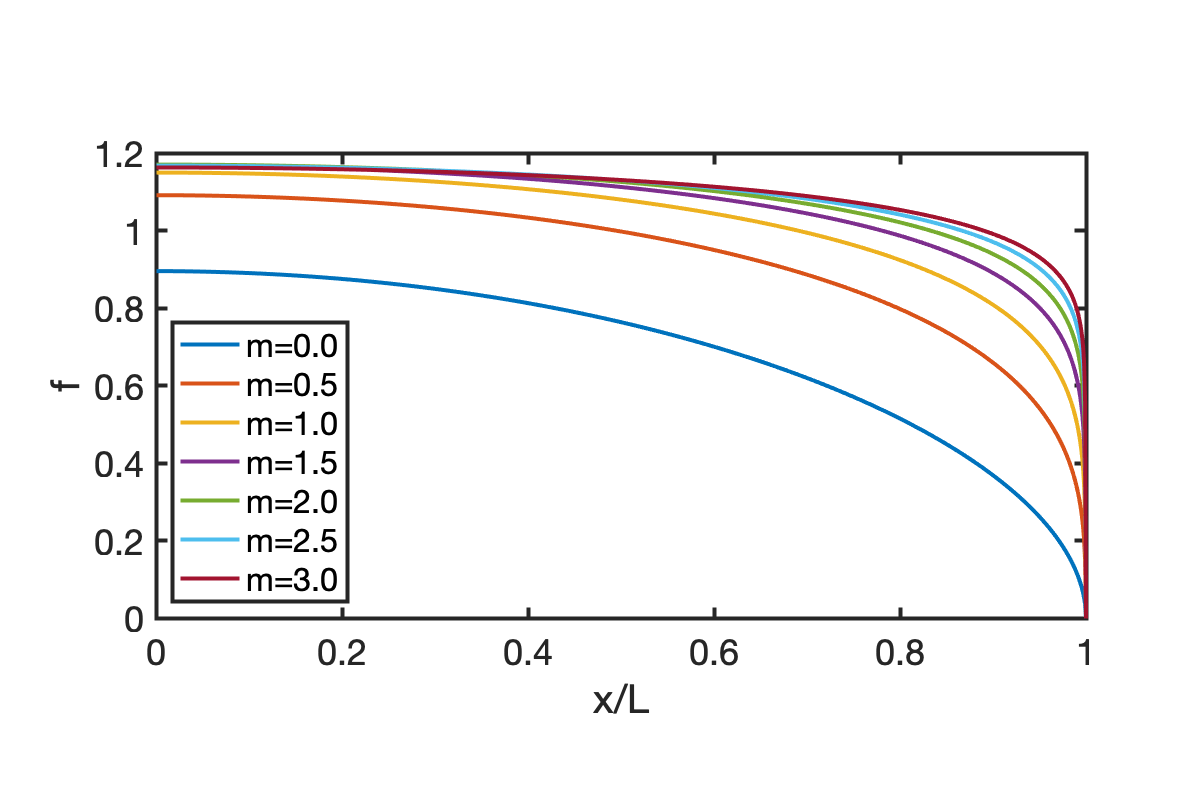

% plot solutions
figure('position',[10 10 600 400])
for i=1:Nload
    plot_self_similar_soln(Grid,U(:,i),n_vec(i),m_vec(i)), hold on
end
xc = Grid.xc;
save('Analytic-solution.mat', 'U','xc');
legend('m=0.0','m=0.5','m=1.0','m=1.5','m=2.0','m=2.5','m=3.0','location','southwest')

The self-similar solutions,$f(x/l)$, for increasing $m$ are shown in the figure. As $m$ increases the solution develops a strong boundary layer, but eventually changes less and less with increasing $m$.

## References

- Zheng et al. (2013) [Fluid drainage from the edge of a porous reservoir](https://doi.org/10.1017/jfm.2012.630), *J Fluid Mech*, **718**, ﻿558-568

## Auxillary functions

#### solve_self_similar_ode

function [u] = solve_self_similar_ode(res,u,n,m,B,N,BC,kmax)
eps_jac = 1e-6;     % perturbation for numerical Jacobian
tol = 1e-6;         % convergence tolerance

nres = norm(res(u,n,m)); ndu = 1; k = 0;
while (nres > tol || ndu > tol) && k < kmax
    Jac_num = comp_jacobian_selfsimilar(res,u,eps_jac,n,m);
    du = solve_lbvp(Jac_num,-res(u,n,m),B,BC.g,N); 
    u = u + du;
    nres = norm(N'*res(u,n,m)); ndu = norm(N'*du);
    k = k+1;
    fprintf('it = %d: nres = %3.2e  ndu = %3.2e\n',k,nres,ndu)
    if k == 1; ndu = 0; end % to allow exit on first iteration
end
if k == kmax; fprintf('Newton-Raphson did not converge in %d iterations.\n',k); end
end

#### plot_self_similar_soln

function [] = plot_self_similar_soln(Grid,u,n,m)


z = linspace(0,1,1e2);
% subplot('Position',[ode_x ode_y subW_ode/figW subH_ode/figH])
plot(Grid.xc,u,'-'), hold on
xlabel 'x/L'
ylabel 'f'
pbaspect([1 .5 1])


end

#### comp_jacobian_selfsimilar

function [J] = comp_jacobian_selfsimilar(r,u,eps,n,m)
N=length(u);
u_perturb=u;
for i=1:N
   u_perturb(i)=u_perturb(i)+eps;
   J(:,i)=(r(u_perturb,n,m)-r(u,n,m))/eps;
   u_perturb(i)=u(i);
end
end
